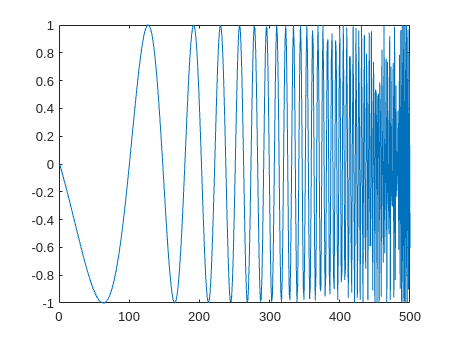

clear all
T=500;
chirp = dsp.Chirp(...
    'Type','Logarithmic',...
    'SweepDirection', 'Unidirectional', ...
    'TargetFrequency', 25, ...
    'InitialFrequency', 0.1,...
    'TargetTime', 15, ...
    'SweepTime', 15, ...
    'SamplesPerFrame', T, ...
    'SampleRate', 35, ...
    'InitialPhase',pi/2);

y= chirp();
figure()
plot(y);

% yoff = [off';y]
% figure()
% plot(yoff);



%% white noise
e = normrnd(0,0.05,T,1);
ye = y+e;

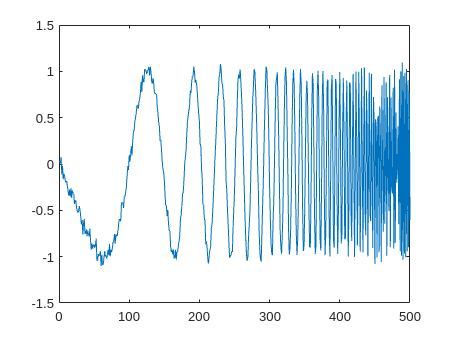

figure()
plot(ye);